## Opgave 2

data = xlsread('Data_M4STI1_2015F_reeksamen.xlsx');
% data = xlsread("Eksamens sæt\15E\M4STI1_2015E_data.xlsx");

Vind_hast = data(:,1);
prodtuktion = data(:,2);


### a.

Lav en lineær regressionsanalyse af produceret vindmøllestrøm som funktion af vindhastighed og skriv regressionsligningen op. Beregn den forventede produktion ved en vindhastighed på 9.5.

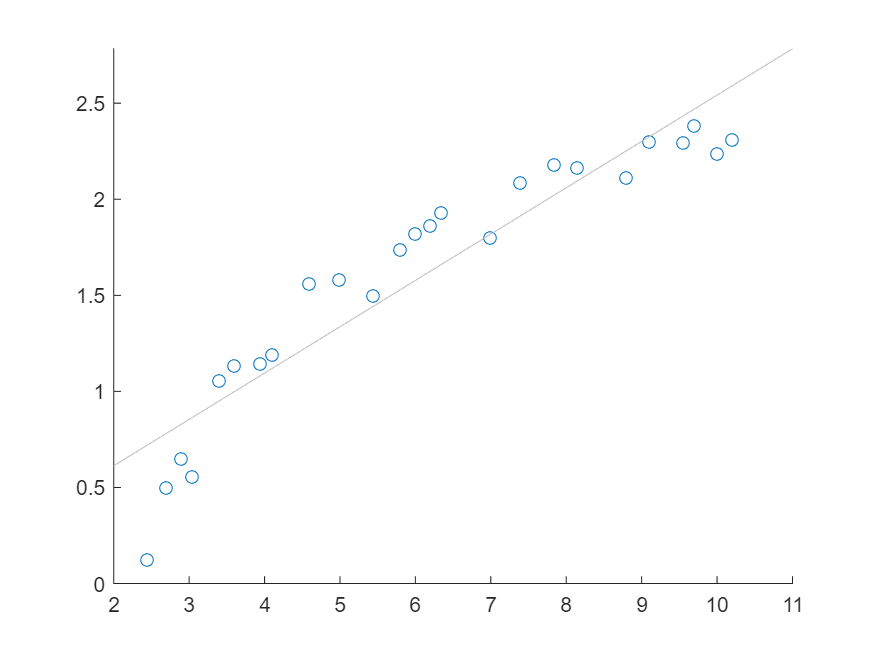

scatter(Vind_hast, prodtuktion)
lsline;

fitlm(Vind_hast, prodtuktion)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)    0.13088      0.12599    1.0388       0.30971
    x1             0.24115     0.019049    12.659    7.5455e-12


Number of observations: 25, Error degrees of freedom: 23
Root Mean Squared Error: 0.236
R-squared: 0.874,  Adjusted R-Squared: 0.869
F-statistic vs. constant model: 160, p-value = 7.55e-12

VI får nu ligningen $y = 0,13088 + x \cdot 0,24115$ 

x = 9.5

x = 9.5000

y = 0.13088 + x * 0.24115

y = 2.4218

**Vindproduktionen forventes at være 2,4218**

### b.

Forklar v.h.a. regressionsanalysens statistikker (f.eks. R-squared og p-value), om modellen beskriver observationerne godt.

Da Vores R værdi er mindre end 0,9  er det ikke et helt godt fit men der oppe af. 